# Plot Turbulence Empirical RSN filt (0.08-0.008)

Plot results from the empirical analysis: turbulence, information flow, information cascade and information transfer obtained in turbulence_empirical_RSN.mlx. 

TBI dataset from OpenNeuro: [https://openneuro.org/datasets/ds000220/versions/1.0.0/file-display/dataset_description.json](https://openneuro.org/datasets/ds000220/versions/1.0.0/file-display/dataset_description.json)

## Load results

clear all
data_path='/Volumes/TBI/TBI_project/TBI_openneuro/timeseries/Schaefer1000_7RSN/outputs/Turbulence_28_03_2022/';
output_path='/Volumes/TBI/TBI_project/TBI_openneuro/timeseries/Schaefer1000_7RSN/outputs/Turbulence_28_03_2022/figures/turbu_all_OpenNeuroTBI_N24_con1_filt/';
addpath '/Users/noeliamartinezmolina/Documents/GitHub/TBI_turbulence_openneuro_current_code/helper functions'
lambda={'0.27','0.24','0.21','0.18','0.15','0.12','0.09','0.06','0.03','0.01'};
cond = {'Controls','Patients'};
cd(data_path)
results = load(sprintf('turbubyRNS_all_measurements_cond1.mat'));
idx_con=[1:1:12]; idx_pat=[13:1:24];
Turbu_RSN_con= results.TurbulenceRSN_sub(:,idx_con,:);
Turbu_RSN_pat= results.TurbulenceRSN_sub(:,idx_pat,:);
cd(output_path)

## Plot turbulence by RSN

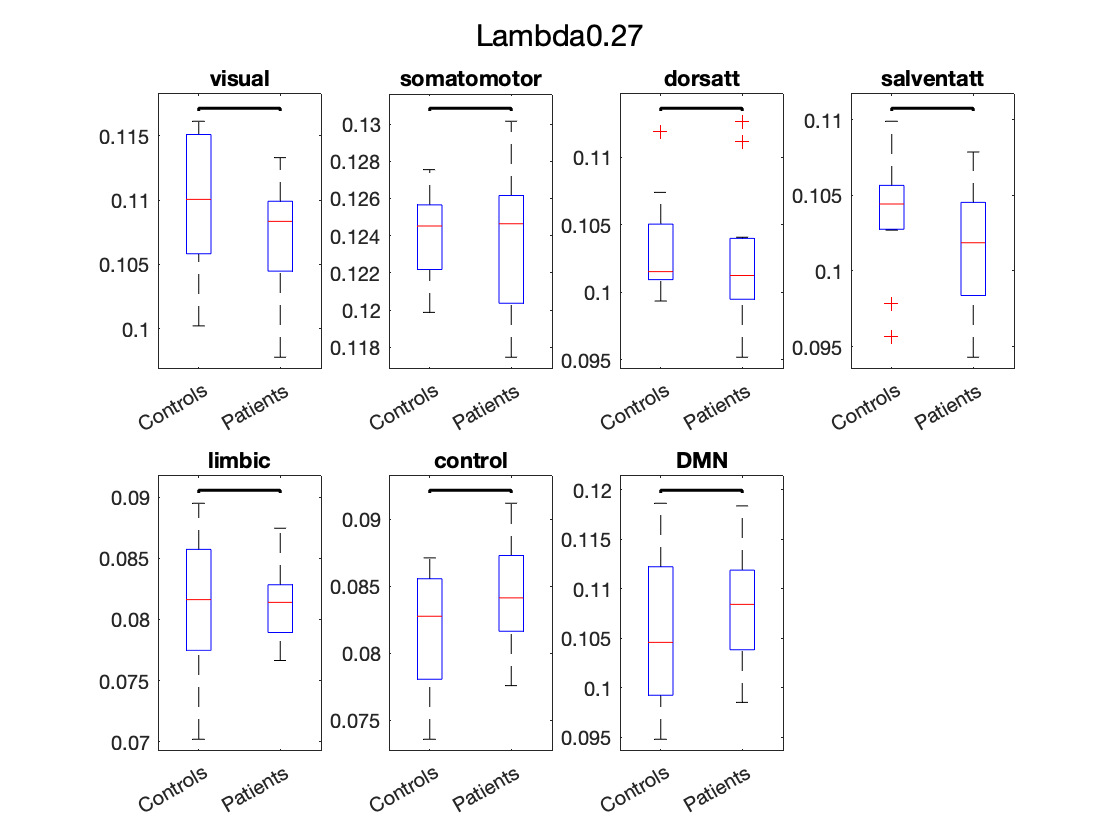

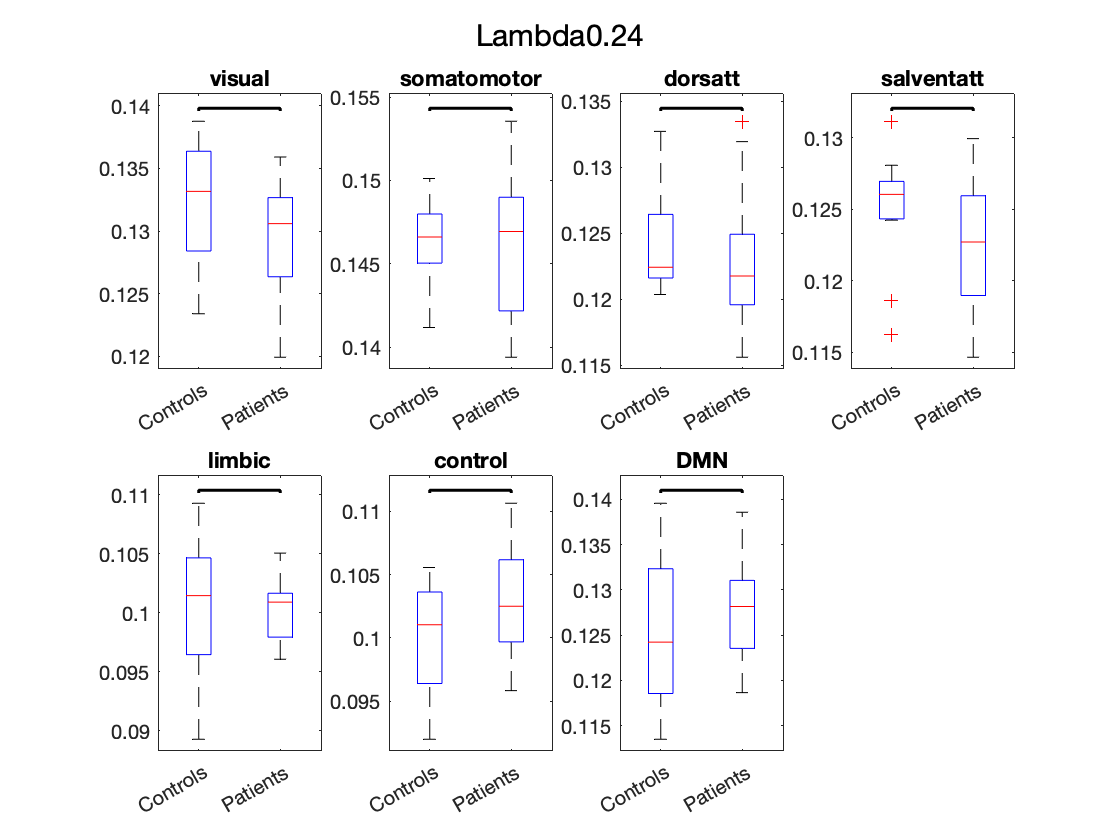

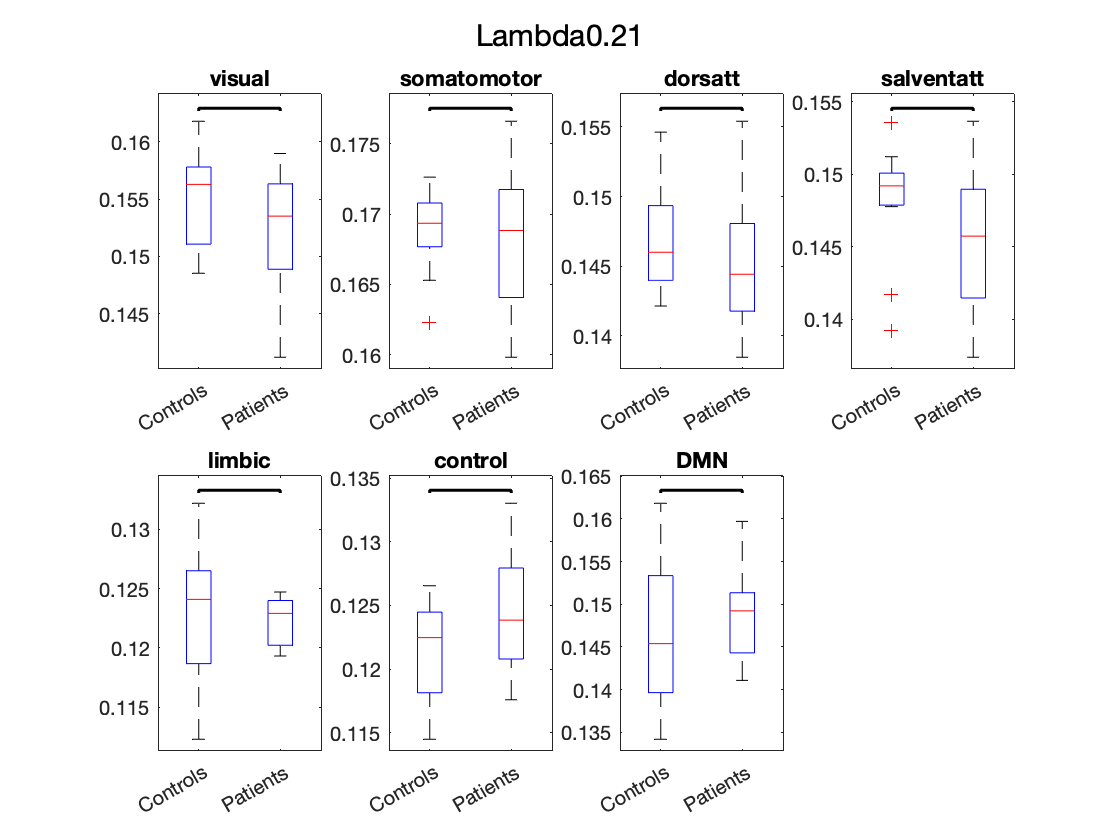

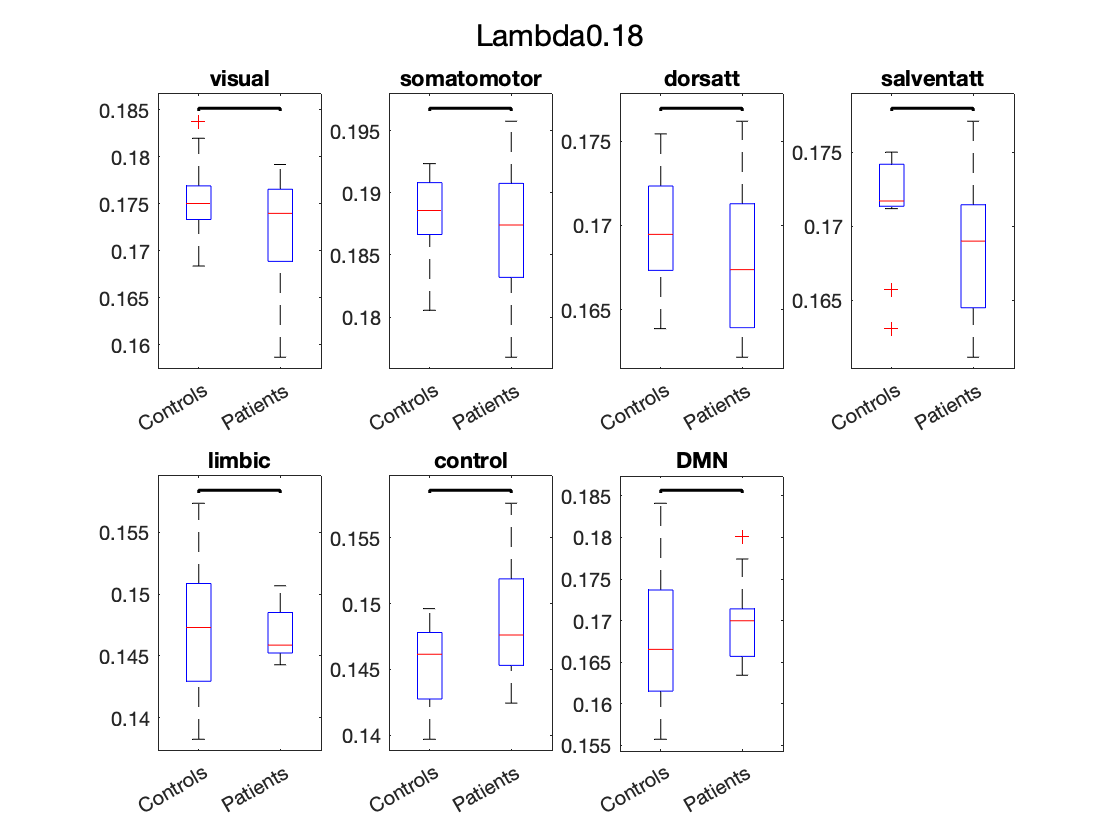

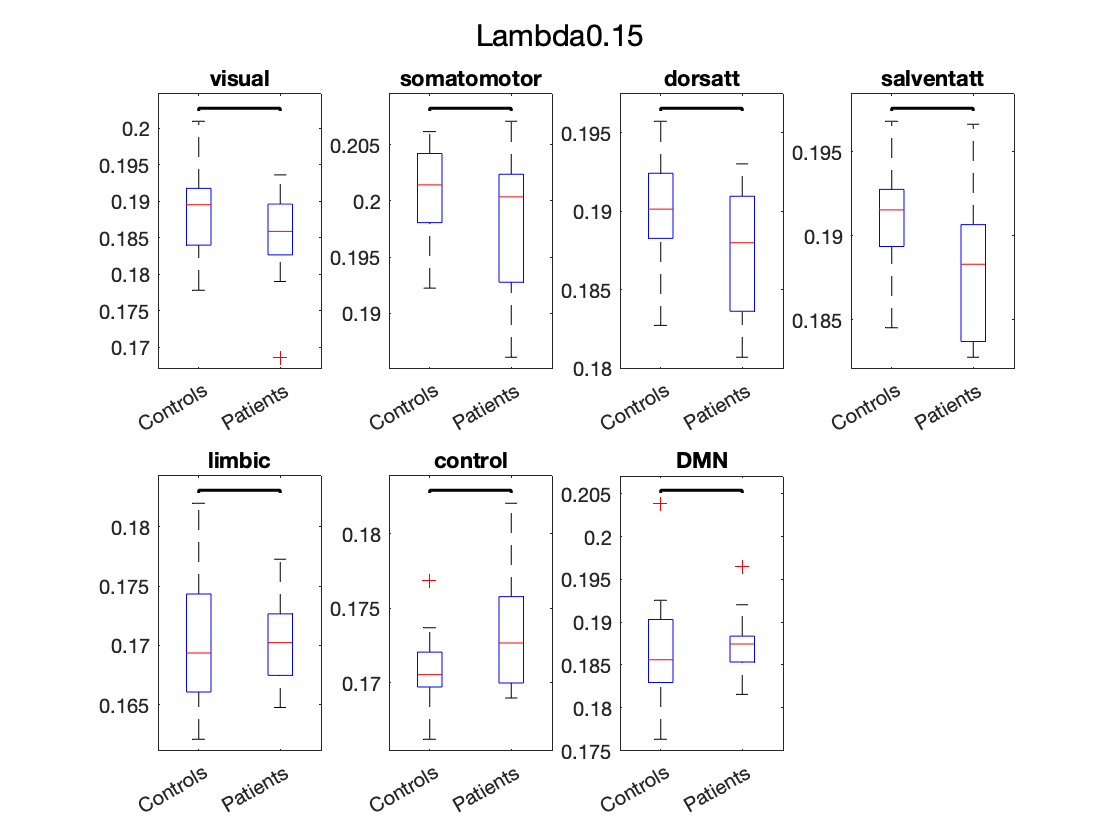

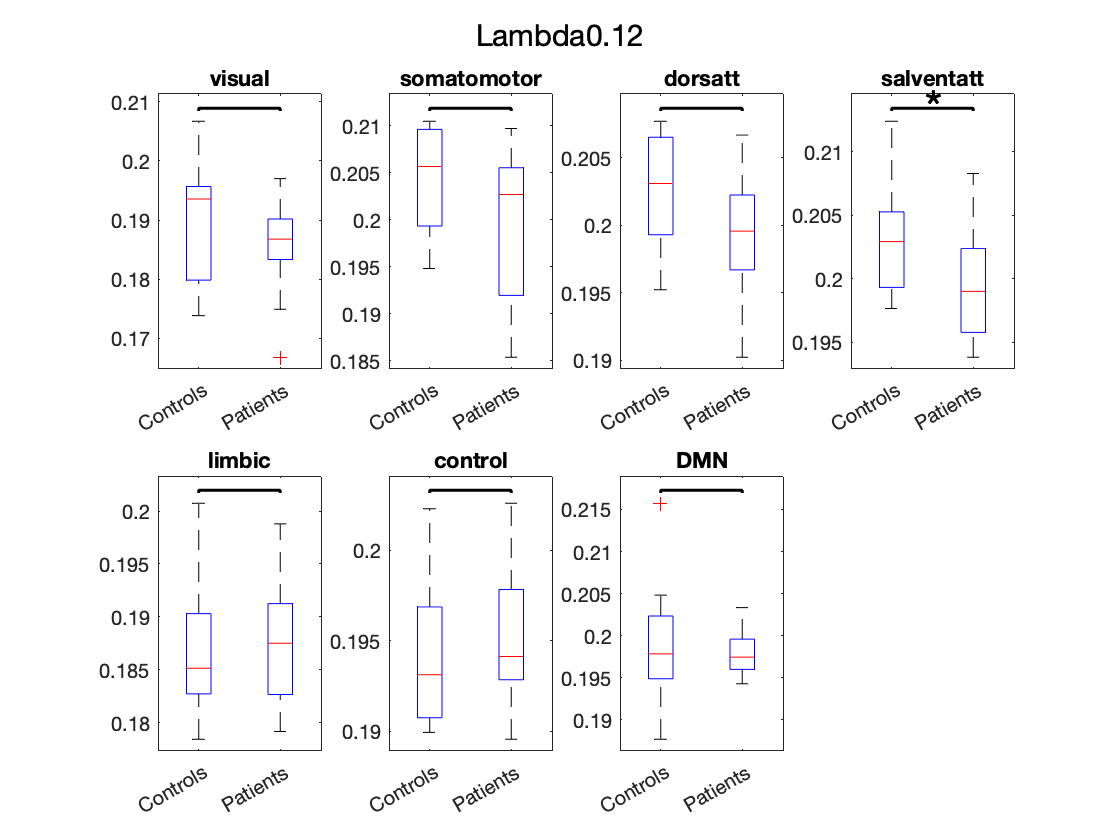

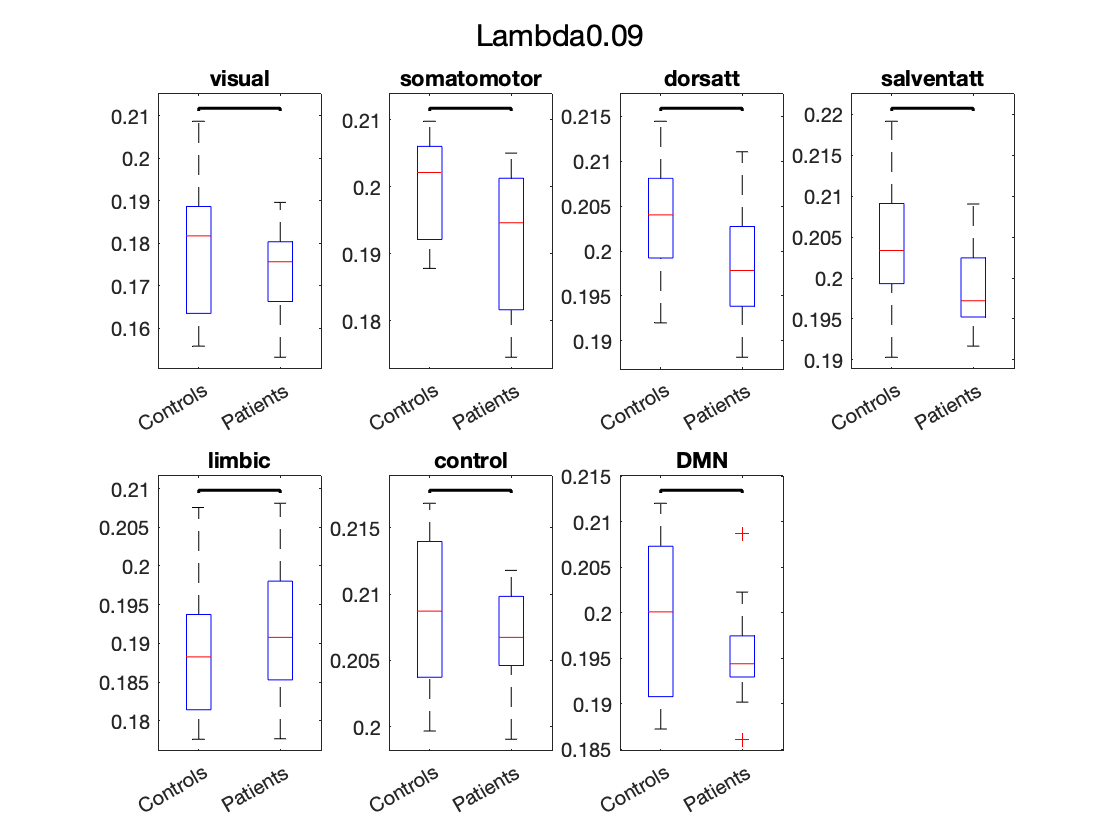

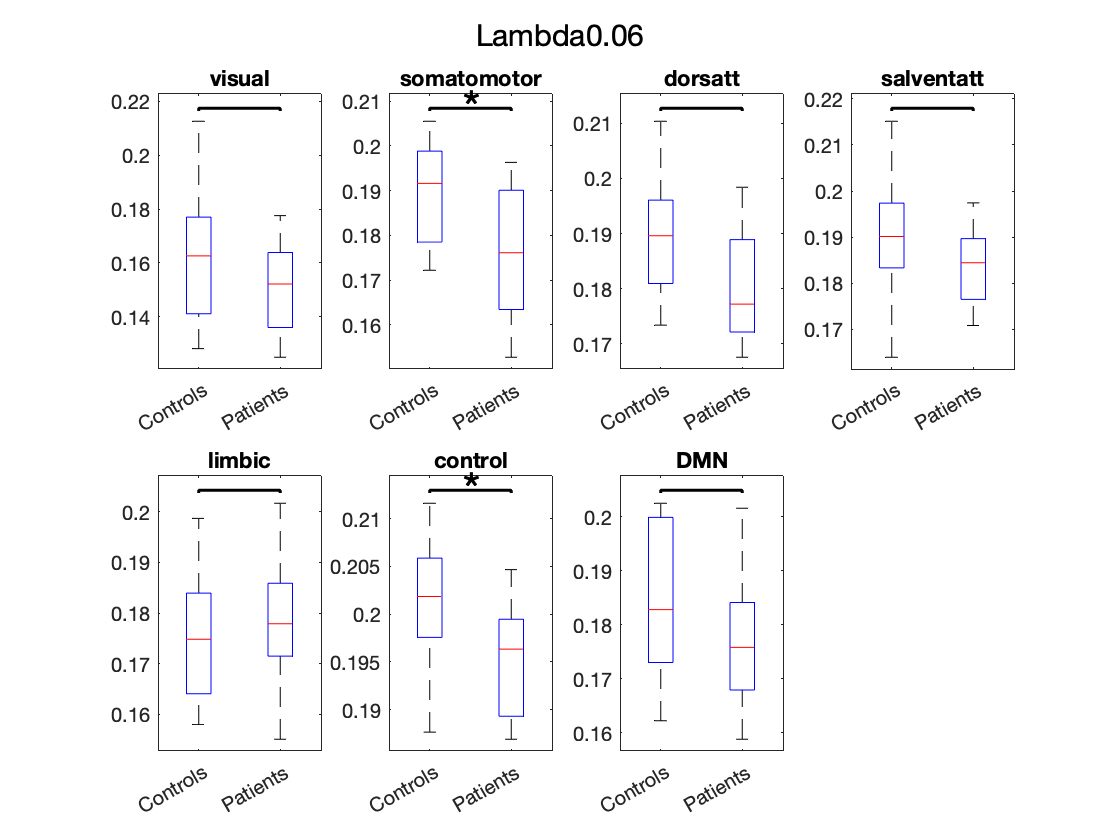

Rsns = {'visual', 'somatomotor','dorsatt','salventatt','limbic','control','DMN'};
for lamb=1:length(lambda)
    figure
    sgtitle (['Lambda' char(lambda(lamb))])
    for jj=1:7 %Loop for networks
        subplot(2,4,jj)
        C = {Turbu_RSN_con(lamb,:,jj) , Turbu_RSN_pat(lamb,:,jj)};
        maxNumEl = max(cellfun(@numel,C));
        Cpad = cellfun(@(x){padarray(x(:),[maxNumEl-numel(x),0],NaN,'post')}, C);
        Cmat = cell2mat(Cpad);
        boxplot(Cmat,'Labels',cond)
        title(Rsns{jj})
        
        [~,pval] = ttest2(Turbu_RSN_con(lamb,:,jj),Turbu_RSN_pat(lamb,:,jj)); % paired t Test
        p(1,jj)=pval; clear pval
        H=sigstar({[1,2]},p(1,jj));
    end
    print(['TurbulencebyRSN RSN Open Neuro TBI (N=24) filt lambda' num2str(lamb)],'-dpng')
end